# Control de sitema bolita - electroimán

22.93 Control Automático

Rocío Parra

2020

Constantes del problema

clearvars; close all;
R = 4;
L = 1;
M = 0.2;
G = 10;

## a) Modelo de espacios de estados no lineal

Existen tres acumuladores de energía en este problema:

- Altura de la bolita $y$ (energía potencial)

- Velocidad de la bolita $\dot{y}$ (energía cinética)

- Corriente en los inductores $i$ (energía magnética)

Por lo tanto, el vector de estados de este problema es:


$$x 
= \pmatrix{x_1 \cr x_2  \cr x_3 } 
= \pmatrix{y \cr \dot y \cr i }}$$


Con lo cual la ecuación de estado es:


$$\dot x = 
\pmatrix{x_2 
\cr -g + \frac{1}{2m} \left[
\left( \frac{x_3+2}{x_1-1} \right)^2 -
\left( \frac{x_3-2}{x_1+1} \right)^2
\right]
\cr -\frac{R}{L} x_3^2 + \frac{1}{L} u
}$$


y la de salida es, trivialmente:


$$y = x_1$$


x = sym('x', [3, 1], 'real');
u = sym('u', 'real');
f = sym('f', [3, 1], 'real');

assume(x(1)< 1);
assumeAlso(x(1) > -1);

f(1) = x(2);
f(2) = - G + ( ( (2+x(3)) / (1-x(1)) )^2 - ( (2-x(3)) / (1+x(1)) )^2 )/(2*M);
f(3) = -R/L * x(3)^2 + 1/L * u

$$f = \left(\begin{array}{c} x_{2}\\ \frac{5\,{\left(x_{3}+2\right)}^{2}}{2\,{\left(x_{1}-1\right)}^{2}}-\frac{5\,{\left(x_{3}-2\right)}^{2}}{2\,{\left(x_{1}+1\right)}^{2}}-10\\ u-4\,{x_{3}}^{2} \end{array}\right)$$

## b) Linealización alrededor del equilibrio, $y = 0$

#### Cálculo de $x_{eq}, u_{eq}: f(u_{eq}, x_{eq}) = \dot x = 0$

x1eq = 0; % x1 = y -> quiero que sea 0 en equilibrio
x2eq = 0; % x2 = y' -> tiene que ser 0 en equilibrio

% busco x3eq tal que f_2(0, 0, x3eq)==0 (no depende de u)
f2eq = subs(f(2), str2sym({'x1'}), x1eq); 
x3eq = double(solve(f2eq==0, x(3)));

xeq = [x1eq; x2eq; x3eq]

xeq =          0
         0
    0.5000


% busco ueq tal que f_3(x3eq, ueq)==0 (es la unica f que depende de u)
f3eq = subs(f(3), str2sym({'x3'}), x3eq);
ueq = double(solve(f3eq==0, u(1)))

ueq = 1

#### Linealización alrededor de $x_{eq}, u_{eq}
$

A = jacobian(f, x)

$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{5\,{\left(x_{3}-2\right)}^{2}}{{\left(x_{1}+1\right)}^{3}}-\frac{5\,{\left(x_{3}+2\right)}^{2}}{{\left(x_{1}-1\right)}^{3}} & 0 & \frac{5\,\left(2\,x_{3}+4\right)}{2\,{\left(x_{1}-1\right)}^{2}}-\frac{5\,\left(2\,x_{3}-4\right)}{2\,{\left(x_{1}+1\right)}^{2}}\\ 0 & 0 & -8\,x_{3} \end{array}\right)$$

B = jacobian(f, u)

$$B = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

A = double(subs(A, str2sym({'x1', 'x2', 'x3', 'u'}), [xeq', ueq]))

A =          0    1.0000         0
   42.5000         0   20.0000
         0         0   -4.0000


B =  double(subs(B, str2sym({'x1', 'x2', 'x3', 'u'}), [xeq', ueq]))

B =      0
     0
     1


Como $y=x_1$:

C = [1, 0, 0];
D = 0;

## d) Aproximación del modelo no lineal con el modelo lineal

Se evaluaron ambos modelos en simultáneo, con una perturbación de tipo escalón, de amplitud $u_{eq}/50=0.02$, aplicada en $t_{step}=0.5s$

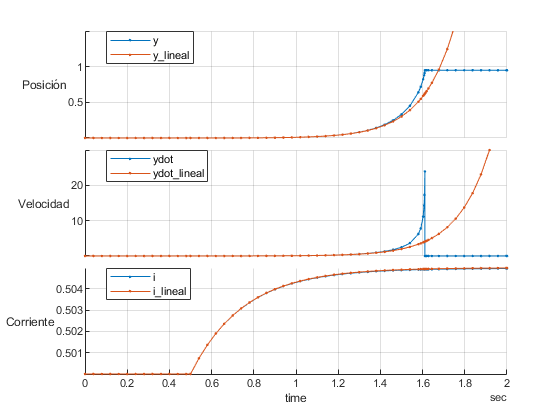

ctrlauto_plot('d')

Se observa que inicialmente el comportamiento de la estimación lineal es bastante similar al del sistema no lineal. Sin embargo, a medida que avanza el tiempo, y la posición se aleja cada vez más de la posición de equilibrio, la linealización deja de ser representativa, hasta llegar al caso final donde la posición queda constante (porque la bolita se queda pegada a uno de los imanes), mientras que el sistema lineal sigue evolucionando.

## e) Analizar la estabilidad del sistema

Los polos del sistema están dados por los autovalores de la matriz $A$. 

eig(A)

ans =     6.5192
   -6.5192
   -4.0000


any(real(eig(A))>0) % verifico si existe al menos un autovalor con parte real > 0

ans = logical
   1


Como uno de estos autovalores tiene parte real positiva, el sistema es inestable.

## f) Control por realimentación de estados

Se realizará un control proporcional lineal que estabilice el sistema a $y=0$, con condiciones iniciales $y(0) = 0.3,\, \dot{y}(0) = 0.2$.

x0 = [0.3; 0.2; 0.0]; % estado inicial (se comienza con corriente 0)
yref = 0;

Se propone calcular dos polos complejos conjugados que en un sistema de segundo orden resultarían en un tiempo de establecimiento de 0.5s, y un máximo sobrepico del 0.1%. El tercero se ubicará a una frecuencia lo suficientemente mayor como para que los resultados no se vean demasiado afectados. 

os = 0.01;
ts = 0.5;

xi = -log(os)/sqrt(pi^2+log(os)^2)

xi = 0.8261

wn = 4/xi/ts

wn = 9.6842

p1 = -xi*wn + 1i*wn*sqrt(1-xi^2);
p2 = conj(p1)

p2 = -8.0000 - 5.4575i

p3 = 10*abs(p1) 

p3 = 96.8423

p = [p1, p2, p3];
K = place(A, B, p)

K =  -625.9048  -70.6596  -84.8423


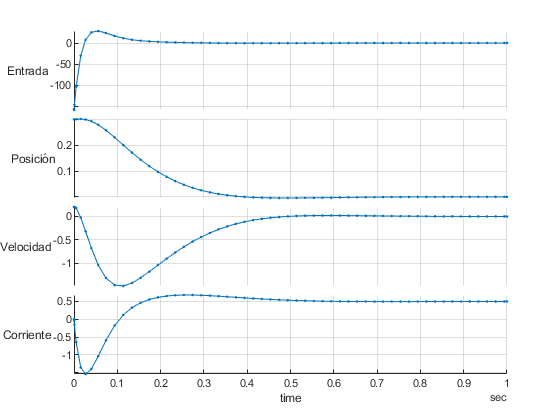

ctrlauto_plot('f')

El sistema se estabiliza en aproximadamente 0.4s, sin sobrepicos demasiado grandes en ninguna de las variables de estado, salvo quizás por un pico de -1.5A en la corriente, que es 3 veces el valor de equilibrio. Sin embargo, la entrada debe llegar a valores más de 100 veces más grandes que el valor de equilibrio, lo cual podría indicar un problema en la parte eléctrica (aunque la variable $u$ no se corresponde exactamente con la tensión de entrada - en principio, está en unidades de amperes/segundo).

## g) Control por realimentación de estados con acción integral

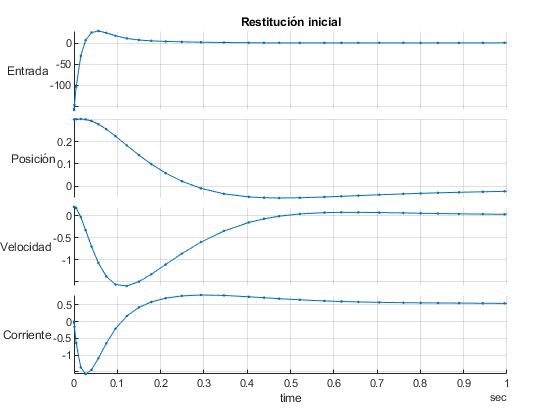

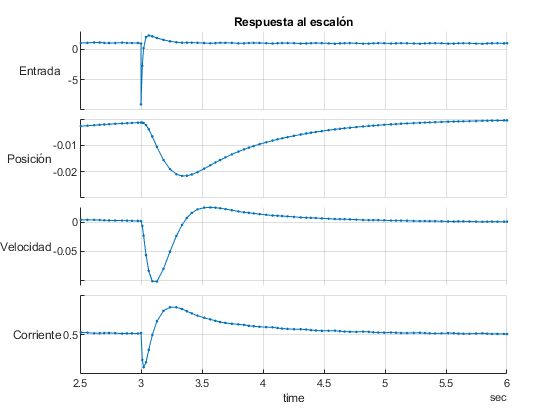

ki = 500.0;
kp = 1.0*K;

ctrlauto_plot('g')

Comparando la restitución desde las condiciones iniciales al equilibrio con los resultados obtenidos para el controlador proporcional, se observa que es considerablemente más lento  Mientras que el caso anterior, la posición se llegaba al equilibrio en aproximadamente 0.4s, al incorporar el integrador no llega a corregir del todo en 3 segundos. Sin embargo, en 2.5 segundos logra recuperarse después de un escalón de $\Delta u=10$ sin error permanente, lo cual no podría haberse conseguido con el controlador anterior. 

## h) Observador de estados

Se propone diseñar e implementar un observador de estados que converja en 0.1s.

Con este objetivo, se colocan los polos más lejos de los polos del sistema, para obtener una respuesta más rápida.

L = -place(A', C', 10*p)'

L = 	1.0e+05 *

    0.0081
    1.4228
    4.2565


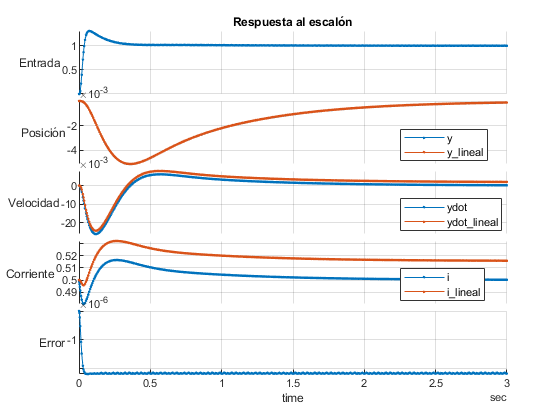

ctrlauto_plot('h')

El error converge satisfactoriamente.